%Getting the data
datacheck41_voltage = table2array(datacheck31(:,5));
datacheck42_voltage = table2array(datacheck32(:,14));
datacheck41_current = table2array(datacheck31(:,6));
datacheck42_current = table2array(datacheck32(:,15));
datacheck41_power = table2array(datacheck31(:,7));
datacheck42_power = table2array(datacheck32(:, 9));
datacheck41_frequency = table2array(datacheck31(:,4));
datacheck42_frequency = table2array(datacheck32(:,8));

%Putting the data together
voltage_3 = [datacheck31_voltage datacheck42_voltage];
current_3 = [datacheck31_current datacheck42_current];
power_3 = [datacheck31_power datacheck42_power];
frequency_3 = [datacheck31_frequency datacheck42_frequency];

%Predicted values set
pred_voltage_3 = [];
pred_current_3 = [];
pred_power_3 = [];
pred_freq_3 = [];
%checking up voltage
for test = (voltage_3(:,1))'
    %Finding the closest cluster
    test_vect = [test;test;test;test];
    dist2 = sum((C_voltage(:,1) - test_vect).^ 2, 1);
    
    closest = dist2 == min(dist2);
    switch closest
        case 1
            pred_voltage_3 = [pred_voltage_3; (std_voltage(1,2)*net_voltage1(((test - mean_voltage(1,1))/std_voltage(1,1)))+mean_voltage(1,2))];
        case 2
             pred_voltage_3 = [pred_voltage_3; (std_voltage(2,2)*net_voltage2(((test - mean_voltage(2,1))/std_voltage(2,1)))+mean_voltage(2,2))];
        case 3
             pred_voltage_3 = [pred_voltage_3; (std_voltage(4,2)*net_voltage3(((test - mean_voltage(3,1))/std_voltage(3,1)))+mean_voltage(3,2))];
        case 4
             pred_voltage_3 = [pred_voltage_3; (std_voltage(4,2)*net_voltage4(((test - mean_voltage(4,1))/std_voltage(4,1)))+mean_voltage(4,2))];
        
    end
end
perf_voltage3_percent = mean(100*(abs( (voltage_3(:,2) - pred_voltage_3)./(voltage_3(:,2)) )))

perf_voltage3_percent = 19.9775

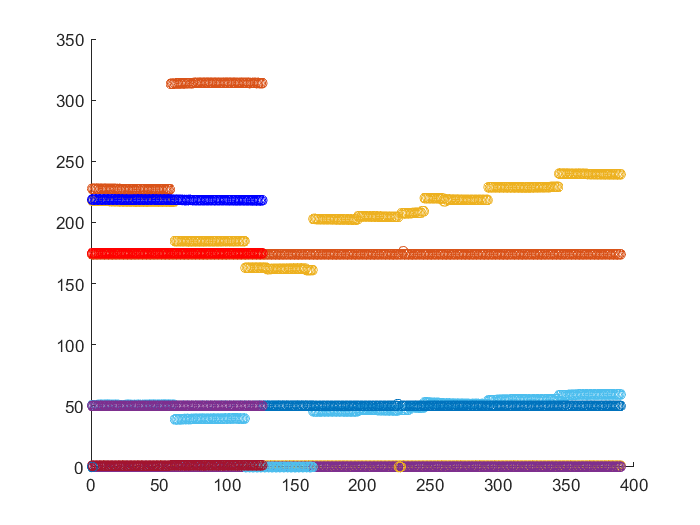


scatter(1:size(pred_voltage_3),pred_voltage_3,'red')
hold on
scatter(1:size(voltage_3(:,2)),voltage_3(:,2),'blue')

%checking up current
for test = (current_4(:,1))'
    %Finding the closest cluster
    test_vect = [test;test;test;test];
    dist2 = sum((C_current(:,1) - test_vect).^ 2, 1);
    
    closest = dist2 == min(dist2);
    switch closest
        case 1
            pred_current_4 = [pred_current_4; (std_current(1,2)*net_current1(((test - mean_current(1,1))/std_current(1,1)))+mean_current(1,2))];
        case 2
             pred_current_4 = [pred_current_4; (std_current(2,2)*net_current2(((test - mean_current(2,1))/std_current(2,1)))+mean_current(2,2))];
        case 3
             pred_current_4 = [pred_current_4; (std_current(3,2)*net_current3(((test - mean_current(3,1))/std_current(3,1)))+mean_current(3,2))];
        case 4
             pred_current_4 = [pred_current_4; (std_current(4,2)*net_current4(((test - mean_current(4,1))/std_current(4,1)))+mean_current(4,2))];
        
    end
end
perf_current4_percent = mean(100*(abs( (current_4(:,2) - pred_current_4)./(current_4(:,2)) )))

perf_current4_percent = 3.8833

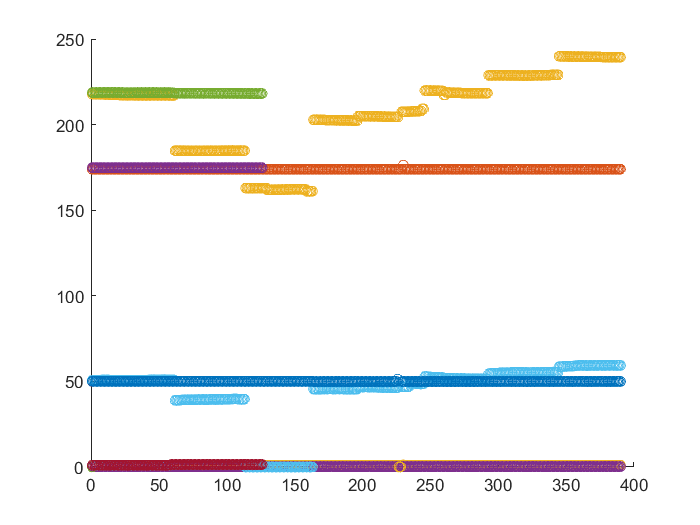

scatter(1:size(pred_current_4),pred_current_4)
hold on
scatter(1:size(current_4(:,2)),current_4(:,2))

%checking up power
for test = (power_4(:,1))'
    %Finding the closest cluster
    test_vect = [test;test;test;test];
    dist2 = sum((C_power(:,1) - test_vect).^ 2, 1);
    
    closest = dist2 == min(dist2);
    switch closest
        case 1
            pred_power_4 = 0;%[pred_power_4; (std_power(1,2)*net_power1(((test - mean_power(1,1))/std_power(1,1)))+mean_power(1,2))];
        case 2
             pred_power_4 = [pred_power_4; (std_power(2,2)*net_power2(((test - mean_power(2,1))/std_power(2,1)))+mean_power(2,2))];
        case 3
             pred_power_4 = [pred_power_4; (std_power(3,2)*net_power3(((test - mean_power(3,1))/std_power(3,1)))+mean_power(3,2))];
        case 4
             pred_power_4 = [pred_power_4; (std_power(4,2)*net_power4(((test - mean_power(4,1))/std_power(4,1)))+mean_power(4,2))];
        
    end
end
perf_power4_percent = mean(100*(abs( (power_4(:,2) - pred_power_4)./(power_4(:,2)) )))

perf_power4_percent = 100

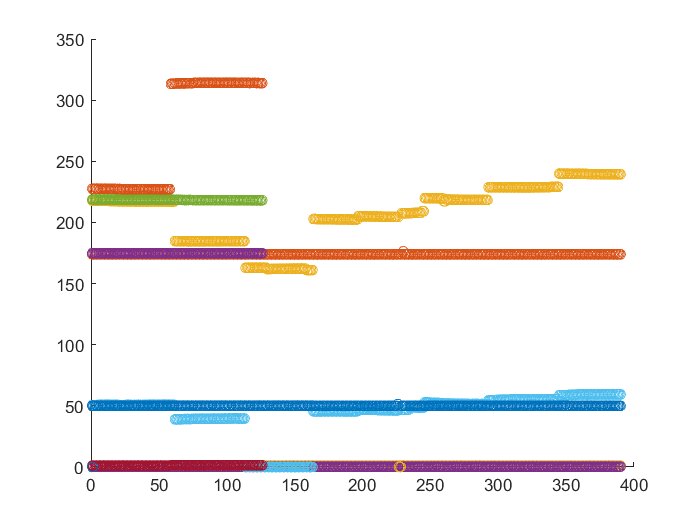

scatter(1:size(pred_power_4),pred_power_4)
hold on
scatter(1:size(power_4(:,2)),power_4(:,2))

%checking up frequency
for test = (frequency_4(:,1))'
    %Finding the closest cluster
    test_vect = [test;test];
    dist2 = sum((C_frequency(:,1) - test_vect).^ 2, 1);
     pred_frequency_4 = [];
    closest = dist2 == min(dist2);
    switch closest
        case 1
            pred_frequency_4 = [pred_frequency_4; (std_frequency(1,2)*net_frequency1(((test - mean_frequency(1,1))/std_frequency(1,1)))+mean_frequency(1,2))];
        case 2
             pred_frequency_4 = [pred_frequency_4; (std_frequency(2,2)*net_frequency2(((test - mean_frequency(2,1))/std_frequency(2,1)))+mean_frequency(2,2))];
        
        
    end
end
perf_frequency4_percent = mean(100*(abs( (frequency_4(:,2) - pred_frequency_4)./(frequency_4(:,2)) )))

perf_frequency4_percent = 0.0273

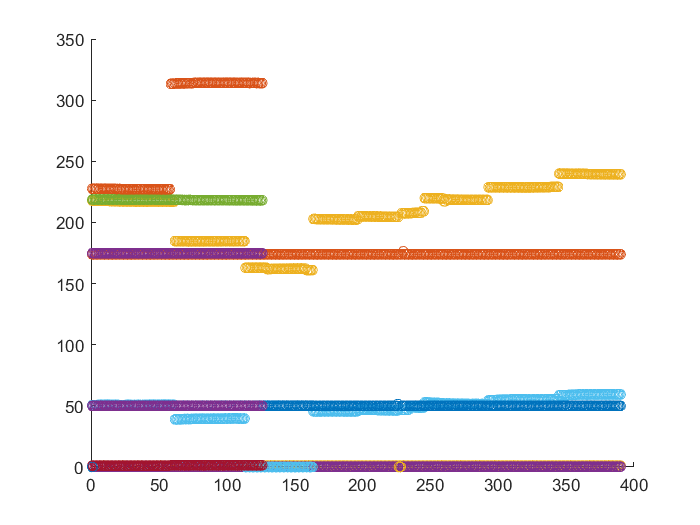

scatter(1:size(pred_frequency_4),pred_frequency_4)
hold on
scatter(1:size(frequency_4(:,2)),frequency_4(:,2))